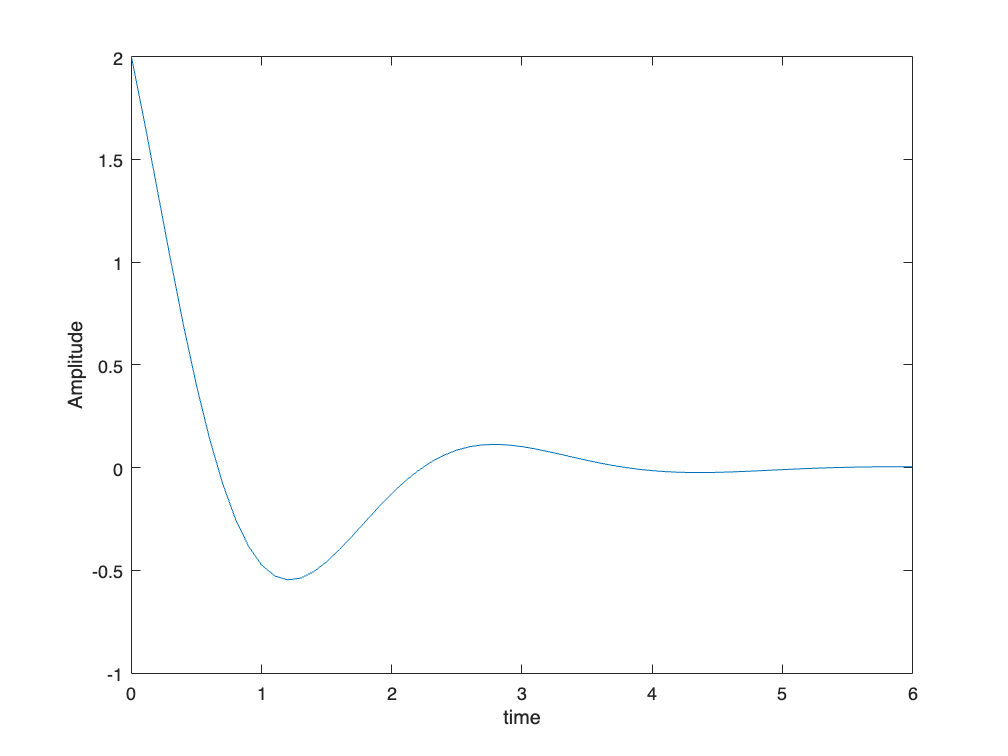

%set up Transfer Function s-plane alpha numberic
s = tf('s');
sysH=(2*s+1)/(s^2+2*s+5);

%set time loop
t=0:0.1:6;
y=impulse(sysH,t);
plot(t,y);
ylabel ('Amplitude')
xlabel ('time')


% go back to time domain with syms s for calculations
syms s

'syms' requires Symbolic Math Toolbox.

H = (2*s+1)/(s^2+2*s+5);
h = ilaplace(H)


